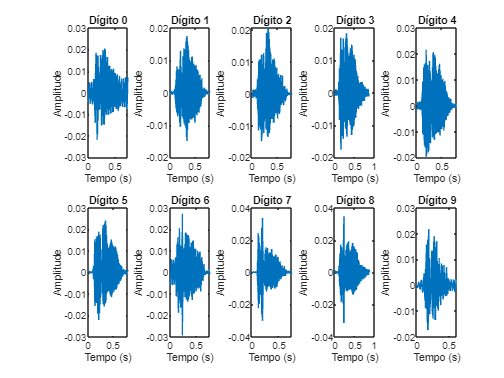

filePath = 'C:\Users\User\Desktop\uni\ATD\Projeto1\55\';
audioFiles = [];
y = cell(1, length(audioFiles));
%Importar os audio usando a função audioread
for i = 0 : 9
    for j = 0 : 49
        file = i + "_55_" + j + ".wav";
        audioFiles = [audioFiles, file];
    end
end
for i = 1:length(audioFiles)
    file = append(filePath, audioFiles{i});
    [y{i}, Fs] = audioread(file);
end

grafico(y, Fs);

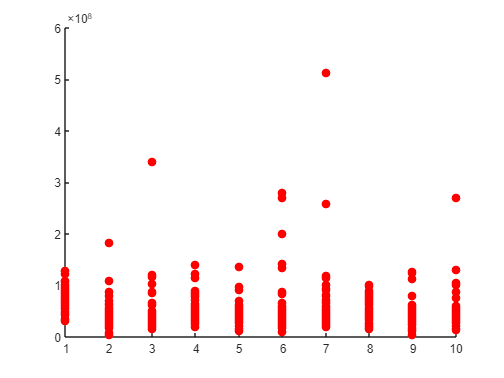


%Adicionar silencio no inicio
limite = 5e-3; %Limite que consideramos silenico ou seja sempre que o intervalo tem a amplitude maxima menor que 0.005
for j = 1:length(y)
    duracaoJanela = 0.002; %Tamanho da janela de pesquisa
    comprimentoJanela = duracaoJanela * Fs;
    comrimentoTotal = length(y{j});
    numeroJanelas = floor(comrimentoTotal / comprimentoJanela);
    yNovo = [];
    for i = 1 : numeroJanelas
        yJanela = y{j}((i-1)*comprimentoJanela+1:comprimentoJanela*i);
        if max(yJanela) > limite
            yNovo = y{j}((i-1)*comprimentoJanela+1:end);
            break;
        end
    end
    y{j} = yNovo;
end


%Adicionar ou remover o silencio no fim
duracaoMax = 0.6; %Duração do audio com mais tempo antes do silencio
for i = 1:length(y)
    if(length(y{i}) < duracaoMax * Fs)
        y{i} = [y{i}; zeros(duracaoMax*Fs - length(y{i}), 1)];
    else
        y{i} = y{i}(1:duracaoMax*Fs);
    end
end


%Normalizar amplitude
amplitudeMax = max(abs(y{1}));
amplitudeMin = min(abs(y{1}));
for i = 2:length(y)
    amplitudeMaxAux = max(abs(y{i}));
    amplitudeMinAux = min(abs(y{i}));
    if amplitudeMaxAux > amplitudeMax
        amplitudeMax = amplitudeMaxAux;
    end
    if amplitudeMinAux < amplitudeMin
        amplitudeMin = amplitudeMinAux;
    end
end

valorMax = amplitudeMax / length(y);
valorMin = amplitudeMin / length(y);
for i = 1:length(y)
    y{i} = y{i} / valorMax;
end


num = {0, 1, 2, 3, 4, 5, 6, 7, 8, 9};

energia = energiaTotal(y);

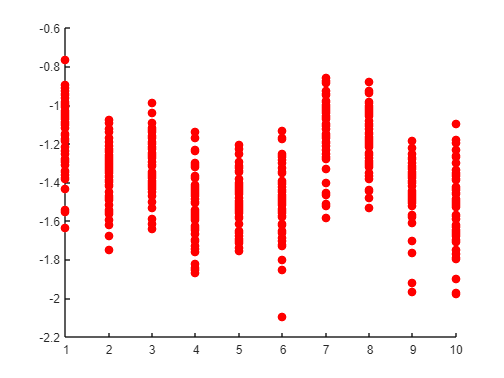


razaoAmp = razaoAmplitude(y);

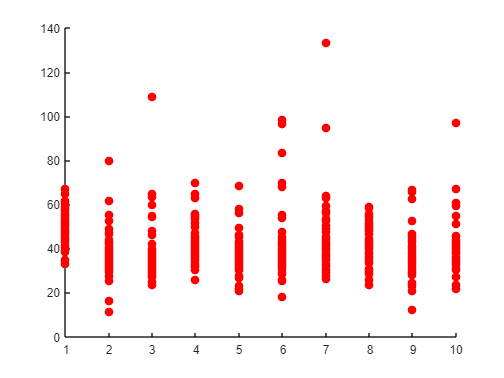


desvioP = desvioPadrao(y);

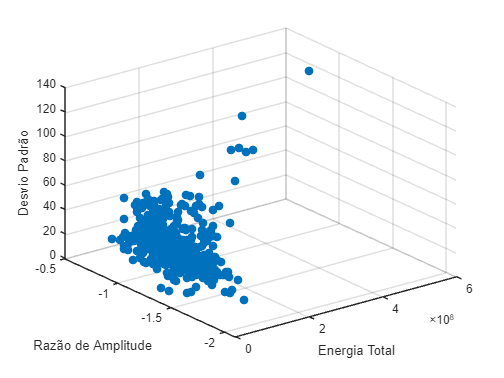


caracteristicas = [energia; razaoAmp; desvioP];
caracteristicas = caracteristicas';
figure;
scatter3(caracteristicas(:,1), caracteristicas(:,2), caracteristicas(:,3), 50, 'filled');xlabel('Energia Total');
xlabel('Energia Total');
ylabel('Razão de Amplitude');
zlabel('Desvio Padrão');

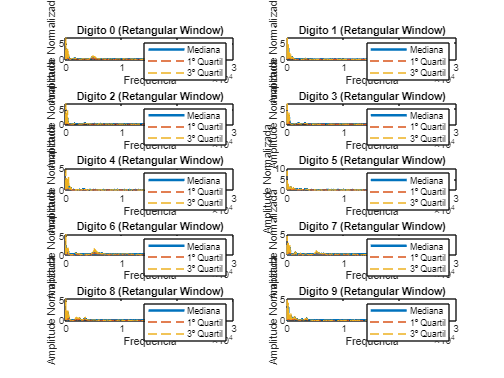


%Meta 2
calcularEspectros(y, Fs, 'Retangular');

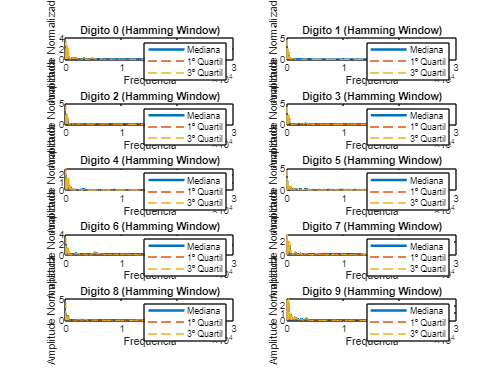

calcularEspectros(y, Fs, 'Hamming');

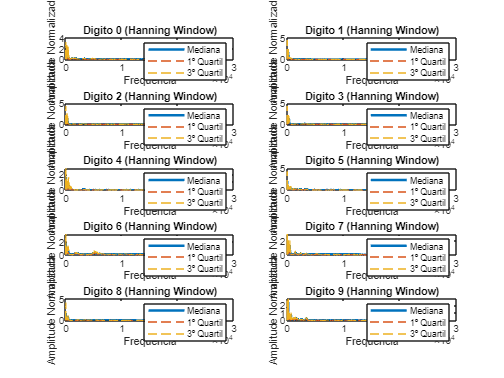

calcularEspectros(y, Fs, 'Hanning');

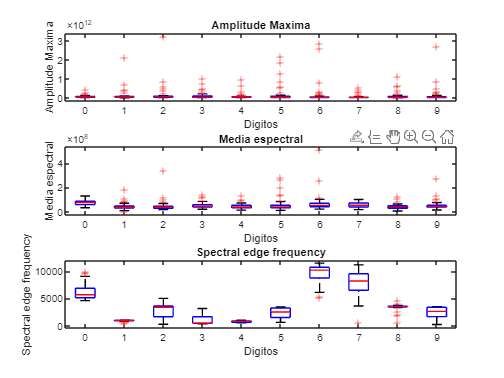


caracteristicasEspectrais = calcularCaracteristicasEspectrais(y, Fs);
plotarCaracteristicas(caracteristicasEspectrais);

function grafico(y, Fs)
for i = 1:10
    subplot(2, 5, i)
    t = (0:length(y{i}) - 1) / Fs;
    plot(t, y{i});
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    title(['Dígito ', num2str(i-1)]);
end
end


function energia = energiaTotal(y)
    figure;
    energia = zeros(1, length(y));
    for i = 1: 10
        for j = 1: 50
            energia(j+50*(i-1))  = sum(y{j+50*(i-1)}.^2);
            scatter(i, energia(j+50*(i-1)), 50,"red" ,"filled", "o");
            hold on;
        end
    end
end

function razaoAmplitude = razaoAmplitude(y)
    figure;
    razaoAmplitude = zeros(1, length(y));
    for i = 1 : 10
        for j = 1 : 50
        amplitudeMax = max(y{j+50*(i-1)});
        amplitudeMin = min(y{j+50*(i-1)});
        razaoAmplitude(j+50*(i-1)) = amplitudeMax/amplitudeMin;
        scatter(i, razaoAmplitude(j+50*(i-1)), 50,"red" ,"filled", "o");
        hold on
        end
    end
end

function desvioPadrao = desvioPadrao(y)
    figure;
    desvioPadrao = zeros(1, length(y));
    for i = 1 : 10
        for j = 1 : 50
            desvioPadrao(j+50*(i-1)) = std(y{j+50*(i-1)});
            scatter(i, desvioPadrao(j+50*(i-1)), 50,"red" ,"filled", "o");
            hold on
        end
    end
end

function calcularEspectros(y, Fs, windowType)
    numDigitos = 10;
    numSamples = length(y{1});

    % Determinar a janela a ser aplicada
    switch windowType
        case 'Hamming'
            window = hamming(numSamples);
        case 'Hanning'
            window = hanning(numSamples);
        otherwise
            window = ones(numSamples, 1);
    end
    
    % Preparar arrays para armazenar os espectros
    espectroMediana = zeros(numSamples/2+1, numDigitos);
    quartil25 = zeros(numSamples/2+1, numDigitos);
    quartil75 = zeros(numSamples/2+1, numDigitos);

    % Calcular FFT, espectro de amplitude e estatísticas para cada dígito
    for digit = 1:numDigitos
        espectro = [];
        for i = 1:50
            index = (digit-1)*50 + i;
            dataFFT = fft(y{index} .* window);
            amplitudeEspectro = abs(dataFFT(1:floor(length(dataFFT)/2)+1)) / length(dataFFT);
            espectro = [espectro, amplitudeEspectro];
        end

        % Calcular mediana e quartis para o espectro de amplitude
        espectroMediana(:, digit) = median(espectro, 2);
        quartil25(:, digit) = quantile(espectro, 0.25, 2);
        quartil75(:, digit) = quantile(espectro, 0.75, 2);
    end

    % Plotar os resultados
    figure;
    freqAxis = linspace(0, Fs/2, numSamples/2+1);
    for digit = 1:numDigitos
        subplot(5, 2, digit);
        plot(freqAxis, espectroMediana(:, digit), 'LineWidth', 2);
        hold on;
        plot(freqAxis, quartil25(:, digit), '--');
        plot(freqAxis, quartil75(:, digit), '--');
        hold off;
        title(['Digito ', num2str(digit-1), ' (', windowType, ' Window)']);
        xlabel('Frequencia');
        ylabel('Amplitude Normalizada');
        legend('Mediana', '1º Quartil', '3º Quartil');
    end
end


function caracteristicasEspectrais = calcularCaracteristicasEspectrais(y, Fs)
    numDigitos = 10; 
    caracteristicasEspectrais = struct();

    for digit = 1:numDigitos
        amplitudeMax = zeros(1, 50);
        frequenciaMax = zeros(1, 50);
        mediaEspectral = zeros(1, 50);
        edgeEspectral = zeros(1, 50);

        for i = 1:50
            index = (digit-1)*50 + i;
            dataFFT = fft(y{index});
            espectroAux = abs(dataFFT(1:floor(length(dataFFT)/2)+1)).^2;
            freqAxis = linspace(0, Fs/2, length(espectroAux));

            % Máximos espectrais e suas posições
            [amplitudeMax(i), idx] = max(espectroAux);
            frequenciaMax(i) = freqAxis(idx);

            % Média espectral
            mediaEspectral(i) = mean(espectroAux);

            % Frequência de corte espectral (95% da energia)
            cumulativeEnergy = cumsum(espectroAux) / sum(espectroAux);
            edgeEspectral(i) = freqAxis(find(cumulativeEnergy >= 0.95, 1));
        end

        caracteristicasEspectrais(digit).maxAmplitude = amplitudeMax;
        caracteristicasEspectrais(digit).maxFrequency = frequenciaMax;
        caracteristicasEspectrais(digit).mean = mediaEspectral;
        caracteristicasEspectrais(digit).edgeFrequency = edgeEspectral;
    end
end

function plotarCaracteristicas(caracteristicasEspectrais)
    numDigitos = 10;

    % Inicializar arrays para armazenar os dados para boxplots
    amplitudesMax = [];
    medias = [];
    edges = [];
    groupLabels = [];

    % Extrair dados e preparar rótulos para o boxplot
    for digit = 1:numDigitos
        amplitudesMax = [amplitudesMax; caracteristicasEspectrais(digit).maxAmplitude'];
        medias = [medias; caracteristicasEspectrais(digit).mean'];
        edges = [edges; caracteristicasEspectrais(digit).edgeFrequency'];
        groupLabels = [groupLabels; repmat(digit, length(caracteristicasEspectrais(digit).maxAmplitude), 1)];
    end

    % Criar um boxplot para cada característica
    figure;
    subplot(3, 1, 1);
    boxplot(amplitudesMax, groupLabels, 'Labels', arrayfun(@num2str, 0:numDigitos-1, 'UniformOutput', false));
    title('Amplitude Maxima');
    ylabel('Amplitude Maxima');
    xlabel('Digitos');

    subplot(3, 1, 2);
    boxplot(medias, groupLabels, 'Labels', arrayfun(@num2str, 0:numDigitos-1, 'UniformOutput', false));
    title('Media espectral');
    ylabel('Media espectral');
    xlabel('Digitos');

    subplot(3, 1, 3);
    boxplot(edges, groupLabels, 'Labels', arrayfun(@num2str, 0:numDigitos-1, 'UniformOutput', false));
    title('Spectral edge frequency');
    ylabel('Spectral edge frequency');
    xlabel('Digitos');
end

